# Multivariate Pattern Analysis (MVPA) to "decode" the  cognitive process 

## Alejandro Santos-Mayo, PhD; 2024

Multivariate approaches to neuroimaging data takes the advantage of using the information contained in other points (electrodes, channels or voxels) to extract the neural activity patterns. Instead of using only the information of one source as classical univariate approaches do, MVPA obt ain and weight the information of several sources to obtain the pattern within them.

load DataAB.mat
% Data A and B corresponds with two matrices [129 channels 1701 time points 51 subjects]

% Electrodes below corresponds with Occipital cluster (e.g. 75 is Oz)
OccipElec = [65 66 67 68 69 70 72 71 73 74 75 76 77 81 82 83 84 88 89 90 94]

figure,subplot(3,1,1), plot(mean(mean(A(OccipElec,:,:),1),3), 'r'), hold on, plot(mean(mean(B(OccipElec,:,:),1),3), 'b'), legend('Condtion A', 'Condition B'), ylabel('A/B occipital (mV)')

diffAB_cluster = A(OccipElec,:,:) - B(OccipElec,:,:);
subplot(3,1,2), plot(mean(mean(diffAB_cluster(:,:,:),1),3), 'k'), hold on, plot(zeros(1,size(A,2)),'k', LineWidth=3), legend('Dif A-B'), ylabel('Difference A-B (mV)')

### Univariate approach

Now, from a univariate perspective, we fit a Student's T-test against 0 using the 51 subjects as distribution. Note that here we are not using any family-wise error (FWER) correction for the shake of simplicty. 

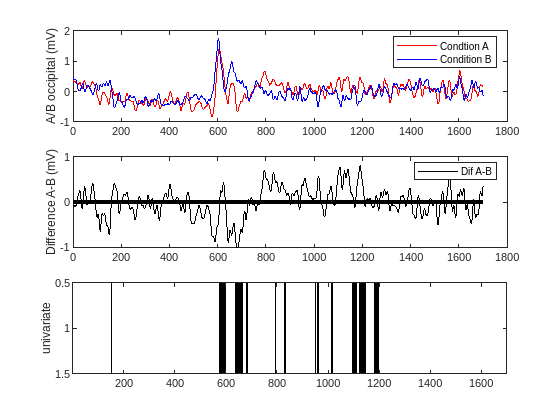

diffAB_univariate = mean(diffAB_cluster,1); % Univariate: 1 elec * 1701 time * 51 subj
h_univariate = ttest(diffAB_univariate, 0, 'tail', 'both', 'Alpha', 0.05, Dim=3); % Ttest in dim 3 => subjects.
subplot(3,1,3),imagesc(h_univariate), colormap([1 1 1; 0 0 0]), ylabel('univariate') % black means statistically significant

### Multivariate approach

Now from a multivariate perspective (specifically here a cross-subject one), we do not mix information of cluster in 1 signal with same weight within them.

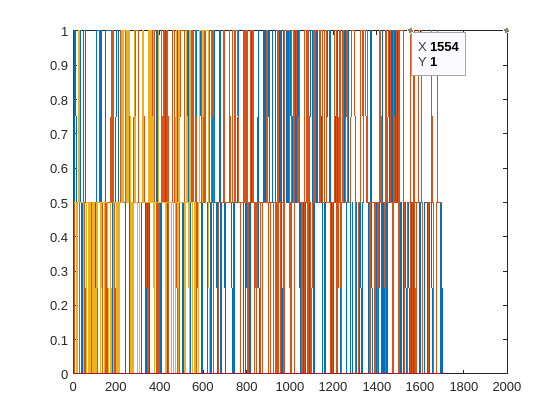

permuted_indices = randperm(51); % 5 4 21 19 51 32 .....
train_indices = permuted_indices(1:50); % N-1 subjects to train classifier.
test_indices = permuted_indices(51); % 1 subject to test classifier.

labels_train = [zeros(50,1); ones(50,1)]; % 0 0 0 0 ... 1 1 1 1 ..
labels_test = [zeros(1,1); ones(1,1)]; % [0 1]

for time = 1: 1701

    train_matrix = transpose([squeeze(A(OccipElec, time, train_indices)) squeeze(B(OccipElec, time, train_indices))]);
    % train_matrix is 100 subj*cond (50 A and 50 B) * 21 occipital electrodes.
    obj = fitcsvm(train_matrix,labels_train);
    % We trained supported Vector Machine (SVM) using 100 subj*cond as observation 
    % and 129 electrodes as features to discriminate.

    test_matrix = transpose([squeeze(A(OccipElec, time, test_indices)) squeeze(B(OccipElec, time, test_indices))]);
    % test_matrix is 1 sbujectec, 2 subj*cond (1 A and 1 B) * 21 occipital electrodes,
    Yhat = predict( obj, test_matrix ); % gives vector of 0,0,1,1,0,0,1,....etc.
    % We predict the label based on electrodes info,
    
    aha = confusionmat(labels_test,Yhat);
    decoding(time) = sum(diag(aha))./sum(sum(aha)); % Calculate hit rate and store in time-vector.
end

figure, plot(decoding)

This script has provided us a decoding rate (based on hit rate) of the signal for each time step using the informaiton contained along the 21 electrodes. However, the result relies on the permutation and random selection of subjects to train or test groups. We need to repeat it to obtain an increase of the decoding resolution 

clear decoding

There are several approachs or methodologies to carry out the analysis: Employing average like here, trials and later mixing information between subjects, withing subject. Here, as an example, we use the decoding approach training the model with average data of all N-1 subjects and testing with the information of the remaining subject. Then, the subject is iterated until all N subjects has been used as test.

for subj = 1:51

train_indices = setdiff(1:51,subj); % all subjects unless 1 to train classifier.
test_indices = subj; % remaining subjects to test classifier.

labels_train = [zeros(50,1); ones(50,1)];
labels_test = [zeros(1,1); ones(1,1)];

for time = 1: 1701

    train_matrix = transpose([squeeze(A(OccipElec, time, train_indices)) squeeze(B(OccipElec, time, train_indices))]);
    % train_matrix is 100 subj*cond (50 A and 50 B) * 21 occipital electrodes.
    obj = fitcsvm(train_matrix,labels_train);
    % We trained supported Vector Machine (SVM) using 100 subj*cond as observation 
    % and 129 electrodes as features to discriminate.

    test_matrix = transpose([squeeze(A(OccipElec, time, test_indices)) squeeze(B(OccipElec, time, test_indices))]);
    % test_matrix is 1 sbujectec, 2 subj*cond (1 A and 1 B) * 21 occipital electrodes,
    Yhat = predict( obj, test_matrix ); % gives vector of 0,0,1,1,0,0,1,....etc.
    % We predict the label based on electrodes info,
    
    aha = confusionmat(labels_test,Yhat);
    decoding(time,subj) = sum(diag(aha))./sum(sum(aha)); % Calculate hit rate and store in time-vector.
end

end

figure, subplot(2,1,1), plot(mean(decoding,2))

To obtain the statistics, we compute the same Student's T test that computed before to check whether A vs B comparison is different using an univariate or multivariate approach. Since hit rate below 0.5 (chance-level) does not have any meaning, right-tailed T test is computed. We use alpha = 0.25 so that same statistical power is confered here.

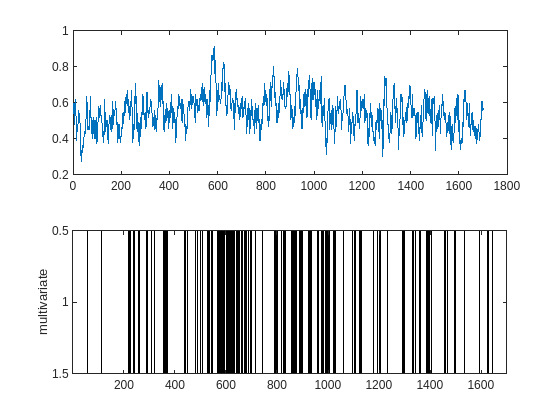

h_multivariate = ttest(decoding, 0.5, 'tail', 'right', 'Alpha', 0.025, Dim=2); % Ttest in dim 3 => subjects.
subplot(2,1,2), imagesc(h_multivariate'), colormap([1 1 1; 0 0 0]), ylabel('multivariate')

### Univariate vs. Multivariate approaches

Finally, we plot the conditions A and B signal from occipital cluster and the statistically significance from both univariate and multivariate approaches.

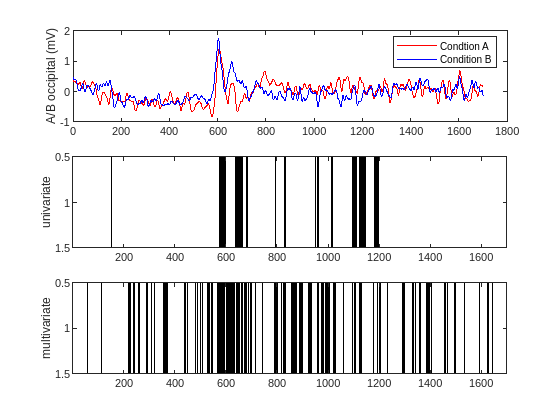

figure
subplot(3,1,1), plot(mean(mean(A(OccipElec,:,:),1),3), 'r'), hold on, plot(mean(mean(B(OccipElec,:,:),1),3), 'b'), legend('Condtion A', 'Condition B'), ylabel('A/B occipital (mV)')
subplot(3,1,2), imagesc(h_univariate), colormap([1 1 1; 0 0 0]), ylabel('univariate')
subplot(3,1,3), imagesc(h_multivariate'), colormap([1 1 1; 0 0 0]), ylabel('multivariate')

Note that FWER is not corrected in any case and it would eliminate the spurious statistical significance.

### Weights of Univariate and Multivariate approaches

For a better a understanding of the differences between both procedures, we can calculate the weight of the model. It means, the importance or contribution of each value  or array of values  to the correct classification of the signal to A or B conditions. For the univariate approach, a standard value of 1 is used. Note that -1 could also be used in a negative comparions in the case of a two-sided analysis.

The exact and unbiased extraction of MVPA weights corresponds with a forward model using a relationship measurement such as covariance or correlation.

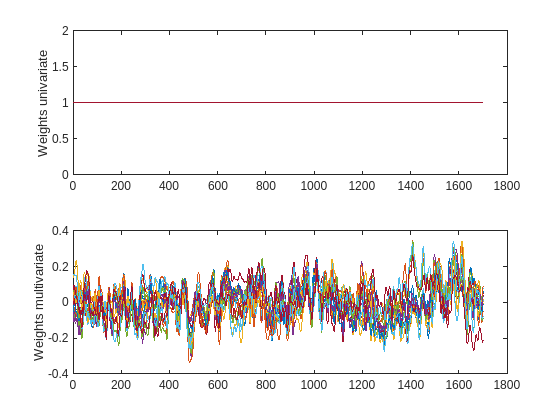


labels_all = [zeros(51,1); ones(51,1)];

for time = 1: 1701
    for elec = 1:21
        all_matrix = transpose([squeeze(A(OccipElec(elec), time, :)) squeeze(B(OccipElec(elec), time, :))]);
        corr = corrcoef(all_matrix, labels_all);
        weights_classifier(time,elec) = corr(1,2);
    end
end

figure, subplot(2,1,1), plot(ones(21,1701)'), ylabel('Weights univariate')
subplot(2,1,2), plot(weights_classifier), ylabel('Weights multivariate')

As we can see, the univariate method employ the same weight for all the 21 occipital electrodes, while the MVPA approach vary the weight and contribution of each channel depending on the time in order to optimize the extraction of the pattern of neural activity.

*Multivariate Pattern Analysis (MVPA) to "decode" the  cognitive process | Alejandro Santos-Mayo, PhD; 2024*